% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time.
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
% 1- ICA on preprocessed epoched data
% What preprocessing has been done:
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLA'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


% 2- PCA 
% - 2.1 PCA across space: across IC space

% For the BLA, BLT and P1, we choose the odd epochs to correspond with
% auditory onset, and even epochs to correspond with tactile onset.
% Extract relevant parameters
fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)';
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Load trial numbers from Excel file


% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

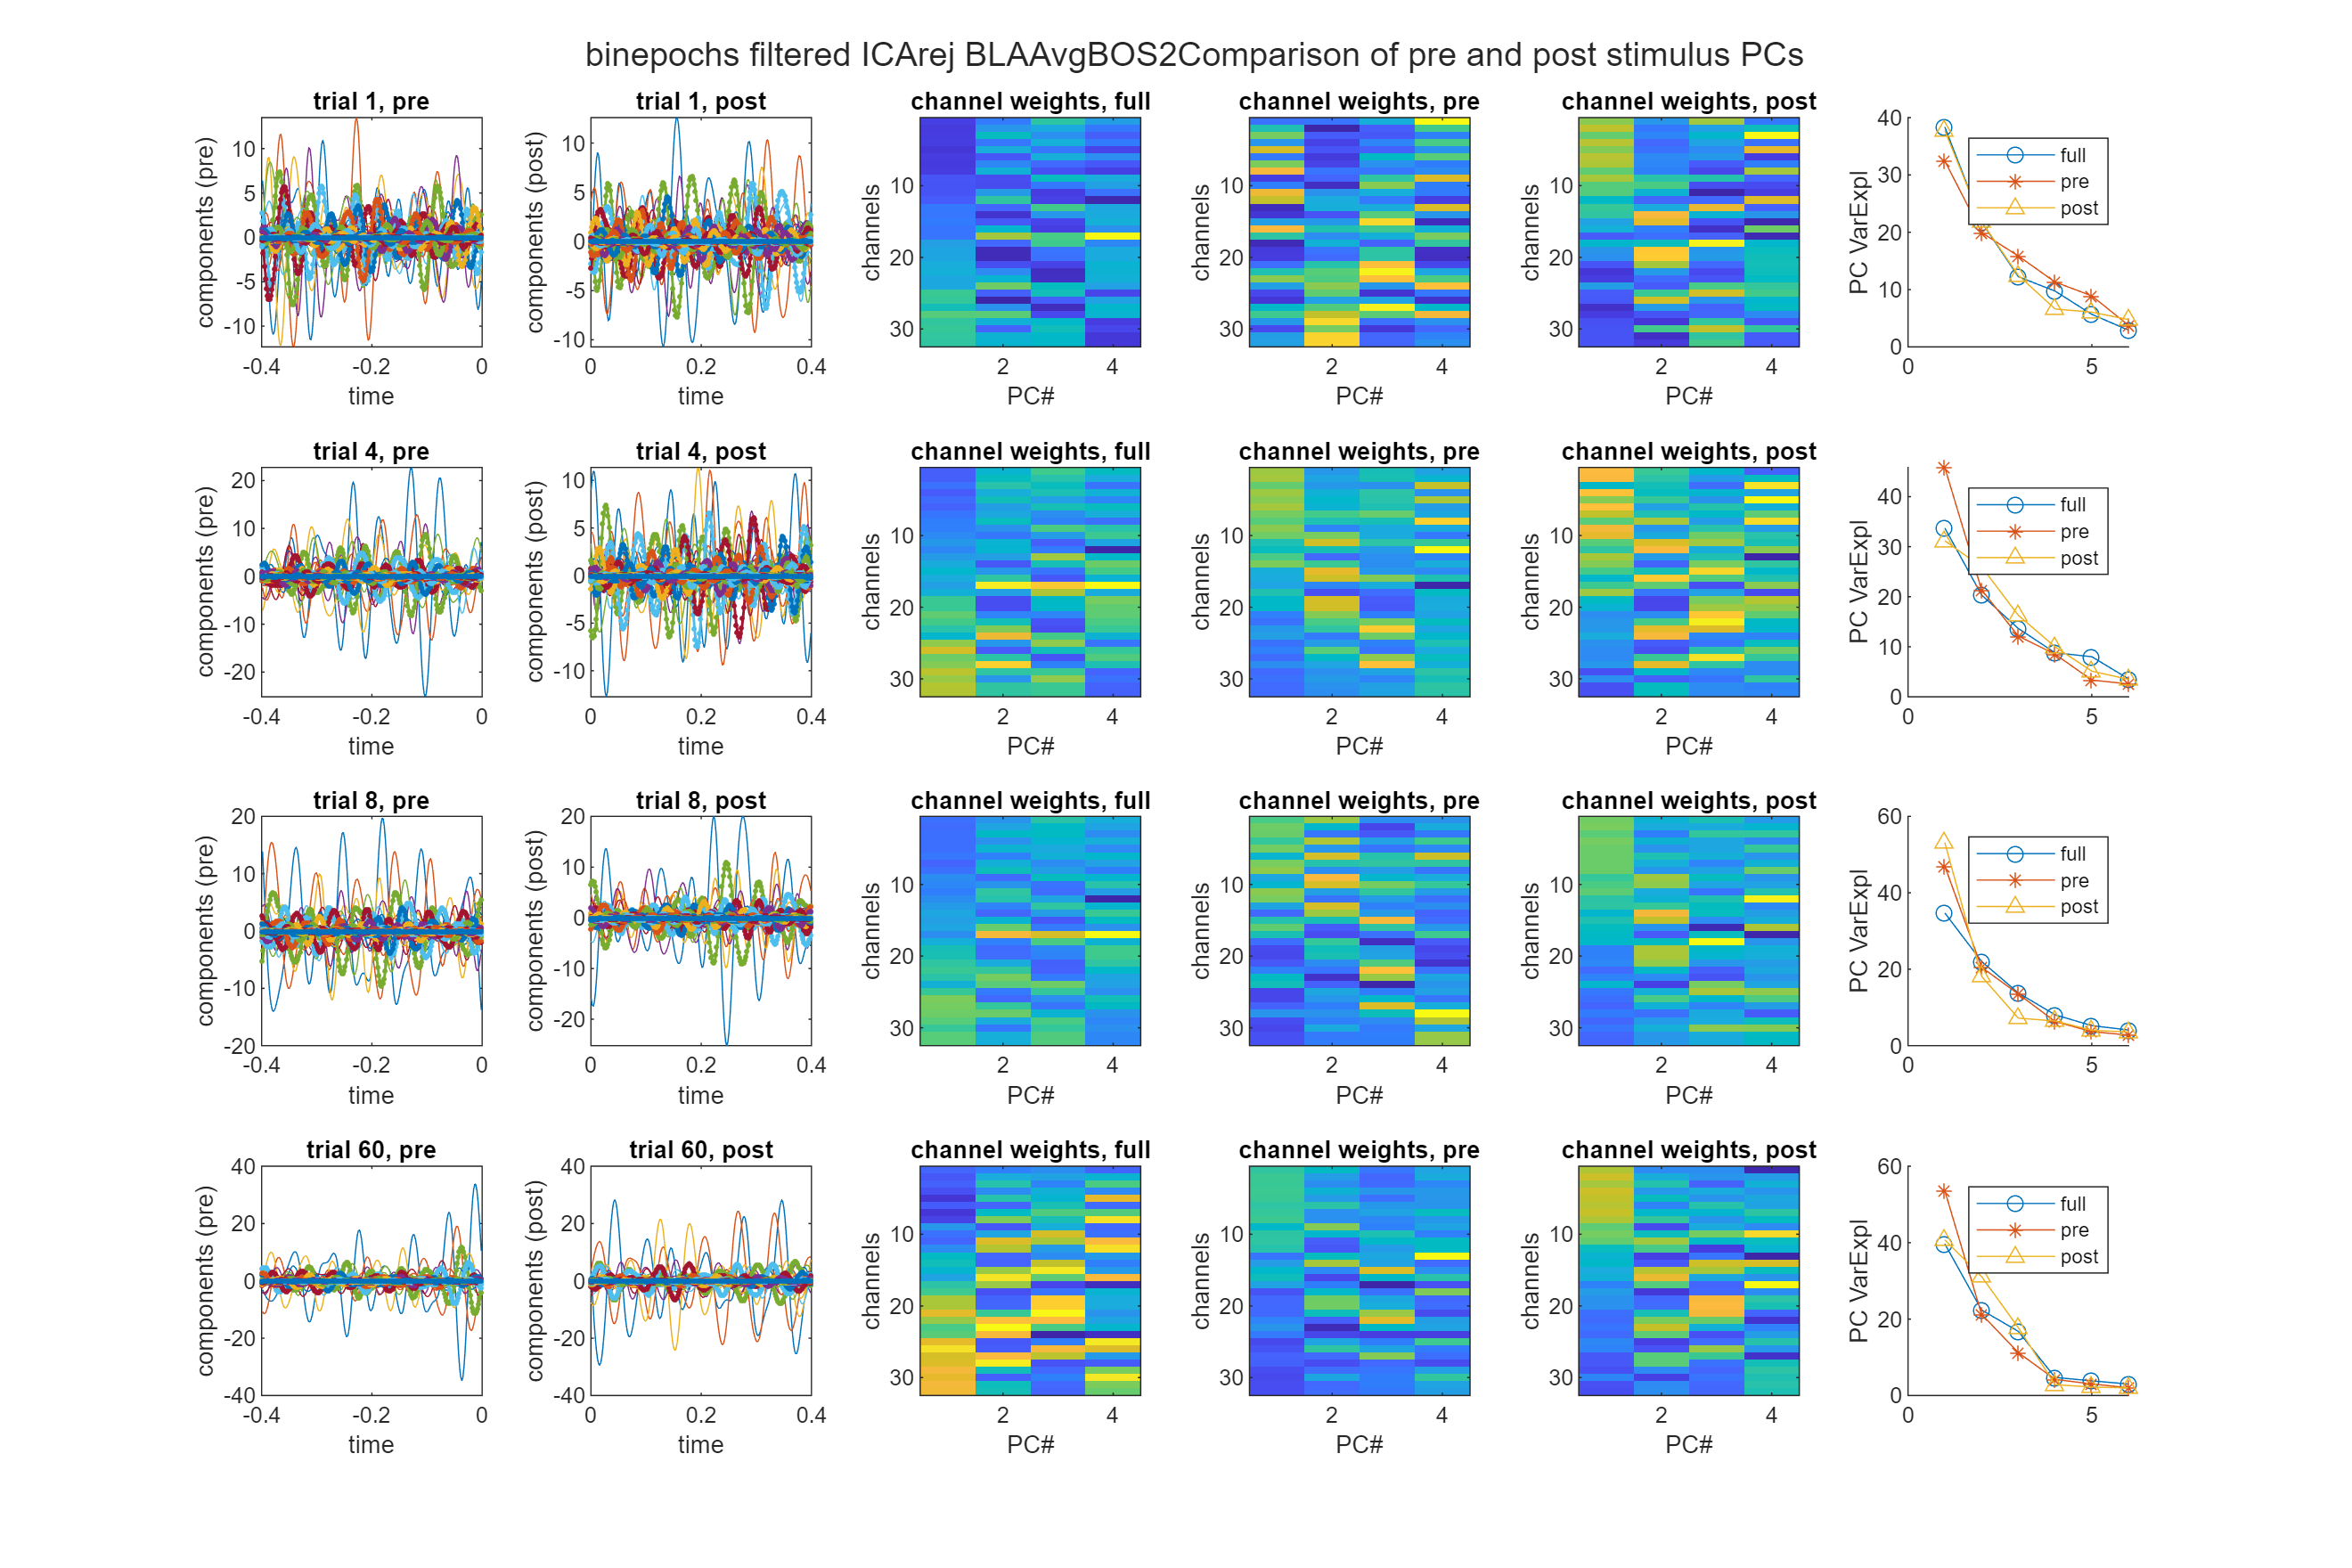

figure('Position', [100, 100, 1200, 800]); % [x, y, width, height]
tiledlayout(4, 6)
% Extract filename for saving
[~, filename, ~] = fileparts(file_path);
sgtitle([filename 'Comparison of pre and post stimulus PCs']);
% Loop through each selected trial
for i = [1 4 8 num_trials]
    trial_data = squeeze(beta_signal(:, :, i)); % Channels x Time

    % PCA on the whole epoch
    [coeff, score, ~, ~, varExpl] = pca(trial_data');
    pre_pcs = score(pre_idx, :);
    post_pcs = score(post_idx, :);

    pre_data = trial_data(:, pre_idx)';
    post_data = trial_data(:, post_idx)';
    pre_data = zscore(pre_data); % Standardize each column
    post_data = zscore(post_data);

    % PCA on pre-stimulus window
    [coeffpre, scorepre, ~, ~, varExplpre] = pca(pre_data);
    
    % PCA on post-stimulus window
    [coeffpost, scorepost, ~, ~, varExplpost] = pca(post_data);

    nexttile
    plot(time_vector(pre_idx), pre_pcs)
    hold on
    plot(time_vector(pre_idx), scorepre, '.-', 'linewidth', 1)
    title(['trial ' num2str(i) ', pre'])
    ylabel('components (pre)')
    xlabel('time')
    
    
    nexttile
    plot(time_vector(post_idx), post_pcs)
    hold on
    plot(time_vector(post_idx), scorepost, '.-', 'linewidth', 1)
    title(['trial ' num2str(i) ', post'])
    ylabel('components (post)')
    xlabel('time')
    
    nexttile
    imagesc(coeff(:, 1:4))
    ylabel('channels')
    xlabel('PC#')
    title('channel weights, full')
    
    nexttile
    imagesc(coeffpre(:, 1:4))
    ylabel('channels')
    xlabel('PC#')
    title('channel weights, pre')
    
    nexttile
    imagesc(coeffpost(:, 1:4))
    ylabel('channels')
    xlabel('PC#')
    title('channel weights, post')
    
    nexttile
    hold on
    plot(varExpl, 'o-')
    plot(varExplpre, '*-')
    plot(varExplpost, '^-')
    xlim([0 6])
    ylabel('PC VarExpl')
    legend({'full', 'pre', 'post'})
end

rank_pre = rank(pre_data);
rank_post = rank(post_data);

disp(['Rank of pre-stimulus data: ', num2str(rank_pre)]);

Rank of pre-stimulus data: 32


disp(['Rank of post-stimulus data: ', num2str(rank_post)]);

Rank of post-stimulus data: 32


[U, S, V] = svd(pre_data, 'econ'); % Compute SVD
num_nonzero_singular_values = sum(diag(S) > 1e-10); % Count nonzero singular values
disp(['Number of independent components in pre_data: ', num2str(num_nonzero_singular_values)]);

Number of independent components in pre_data: 32


[U, S, V] = svd(post_data, 'econ'); % Compute SVD
num_nonzero_singular_values_post = sum(diag(S) > 1e-10); % Count nonzero singular values
disp(['Number of independent components in pre_data: ', num2str(num_nonzero_singular_values_post)]);

Number of independent components in pre_data: 32


% Initialize results matrix (Trials x PCs)
num_pcs = 32; % Number of Principal Components to extract
pc_diff_squared = zeros(num_trials, num_pcs);
pc_cumulative_explained = zeros(num_trials, num_pcs);

% Initialize matrix for normalized values
pc_diff_squared_z = zeros(size(pc_diff_squared));

% Figure 1 Panel A: Cumuluative Sum vs. PCs
% Loop through each selected trial
for i = 1:num_trials
    if strcmp(condition, 'BLA') || strcmp(condition, 'BLT')
        post_window = [0, 0.4];  % Post-stimulus window (0ms to +400ms)
    elseif strcmp(condition, 'P1')
        post_window = [0, 1.020];  % Post-stimulus window (0ms to +1020ms)
    elseif strcmp(condition, 'P2')
        % Read data for both conditions
        trials_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        trials_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
        
        if ismember(epoch_trials(i), trials_500ms)
            post_window = [0, 1.020];  % 500ms condition
        elseif ismember(epoch_trials(i), trials_2000ms)
            post_window = [0, 2.400];  % 2000ms condition
        else
            continue; % Skip trials not in either list
        end        
        
    elseif strcmp(condition, 'P3')
        trials_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        trials_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');

        if ismember(epoch_trials(i), trials_500ms)
            post_window = [0, 1.020];  % 500ms condition
        elseif ismember(epoch_trials(i), trials_missing)
            post_window = [0, 1.020];  % missing condition
        else
            continue; % Skip trials not in either list
        end        
        
    end

    post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));
    trial_data = squeeze(beta_signal(:, :, i)); % Channels x Time

    % PCA on pre-stimulus window
    pre_data = trial_data(:, pre_idx)';
    [~, pre_score, latent_pre, ~, explained_pre] = pca(pre_data);
    
    % PCA on post-stimulus window
    post_data = trial_data(:, post_idx)';
    [~, post_score, latent_post, ~, explained_post] = pca(post_data);

    % Compute difference of sum, and square
    pc_diff = sum(post_score, 1) - sum(pre_score, 1); % Sum across time, subtract pre from post

    pc_diff_squared(i,:) = pc_diff.^2; % Square

    pc_mean = mean(pc_diff_squared(i, :));  % Mean across PCs for this trial
    pc_std = std(pc_diff_squared(i, :));   % Standard deviation across PCs for this trial
    
    % Avoid division by zero
    if pc_std == 0
        pc_std = 1;
    end
    
    % Compute z-score normalized values within the trial
    pc_diff_squared_z(i, :) = (pc_diff_squared(i, :) - pc_mean) / pc_std;
        
    % Compute cumulative sum of explained variance
    cumulative_explained_pre = cumsum(explained_pre);
    cumulative_explained_post = cumsum(explained_post);
    pc_cumulative_explained (i,:) = cumulative_explained_post - cumulative_explained_pre; 
end

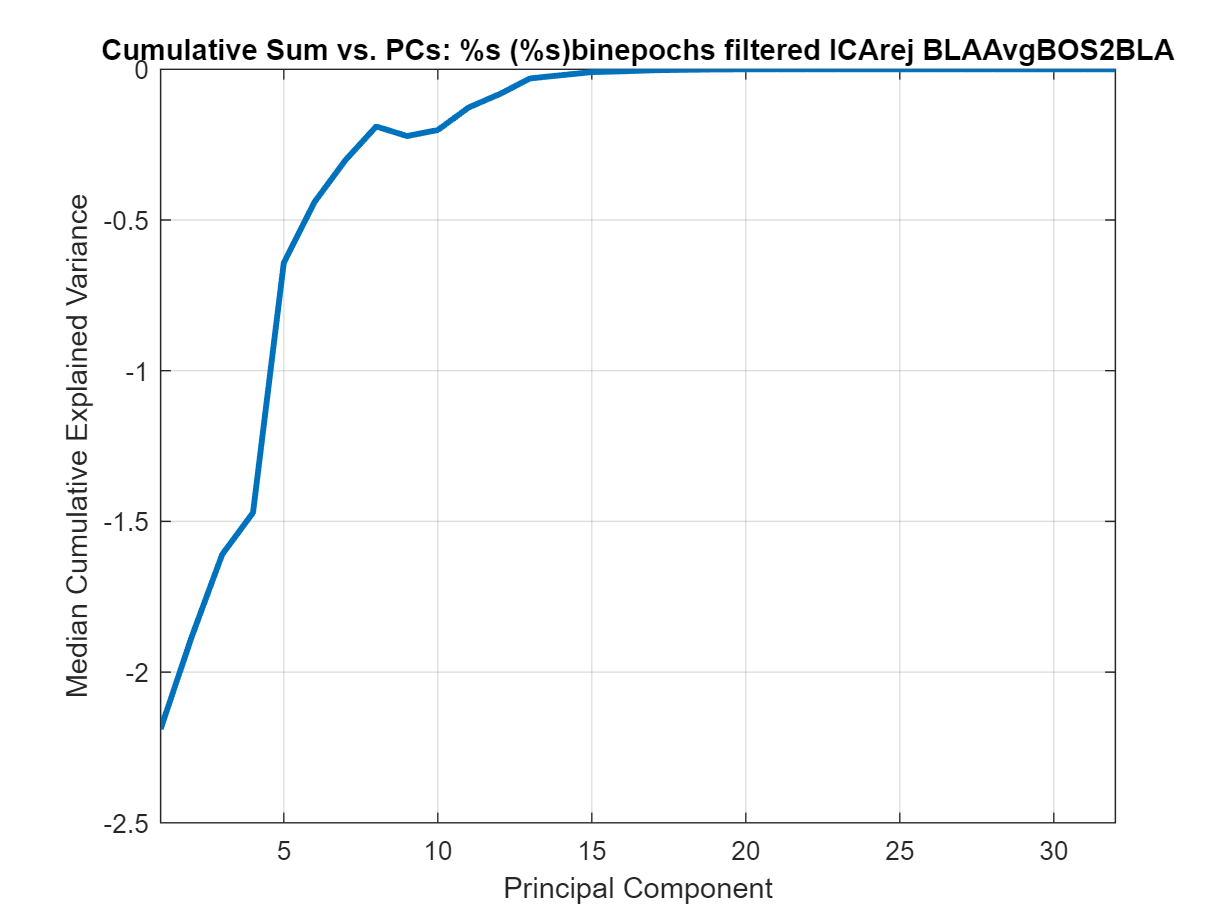

% Compute trial median across rows (trials)
median_cumulative_explained = median(pc_cumulative_explained, 1);
% Plot cumulative sum vs. PCs
figure;
plot(1:length(median_cumulative_explained), median_cumulative_explained, 'LineWidth', 2);
xlabel('Principal Component');
ylabel('Median Cumulative Explained Variance (Post-Pre stimulus)');
% sgtitle([filename 'Comparison of pre and post stimulus PCs']);
title(['Cumulative Sum vs. PCs: ', filename, condition]);
grid on;
xlim([1, length(median_cumulative_explained)]);

% ylim([0, 100]); % Assuming cumulative variance percentage

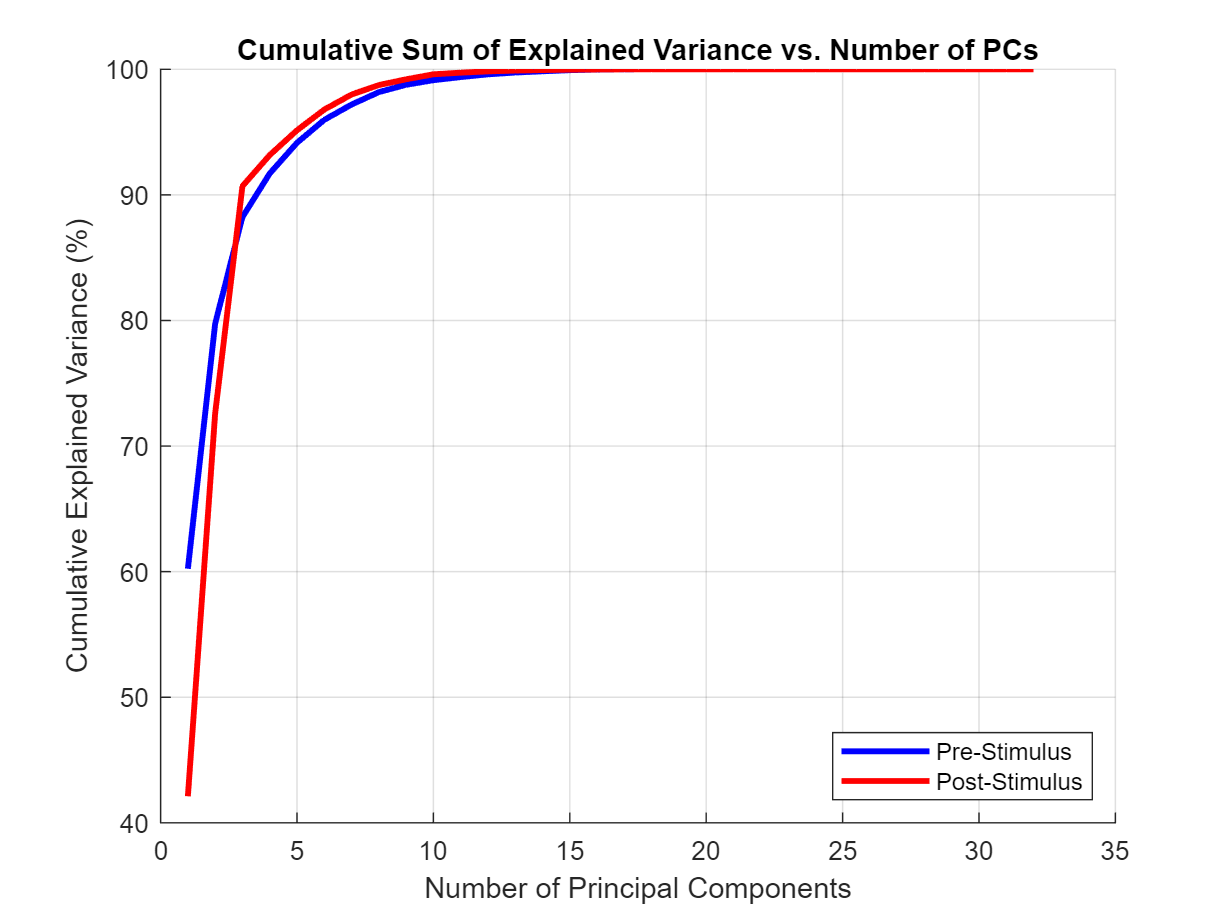

% Compute cumulative sum of explained variance
cumulative_explained_pre = cumsum(explained_pre);
cumulative_explained_post = cumsum(explained_post);

% Define number of PCs (x-axis)
num_pcs_pre = length(cumulative_explained_pre);
num_pcs_post = length(cumulative_explained_post);

% Plot cumulative variance explained
figure;
hold on;
plot(1:num_pcs_pre, cumulative_explained_pre, 'b-', 'LineWidth', 2, 'DisplayName', 'Pre-Stimulus');
plot(1:num_pcs_post, cumulative_explained_post, 'r-', 'LineWidth', 2, 'DisplayName', 'Post-Stimulus');
hold off;

% Formatting the plot
xlabel('Number of Principal Components');
ylabel('Cumulative Explained Variance (%)');
title('Cumulative Sum of Explained Variance vs. Number of PCs');
legend('Location', 'southeast');
grid on;    

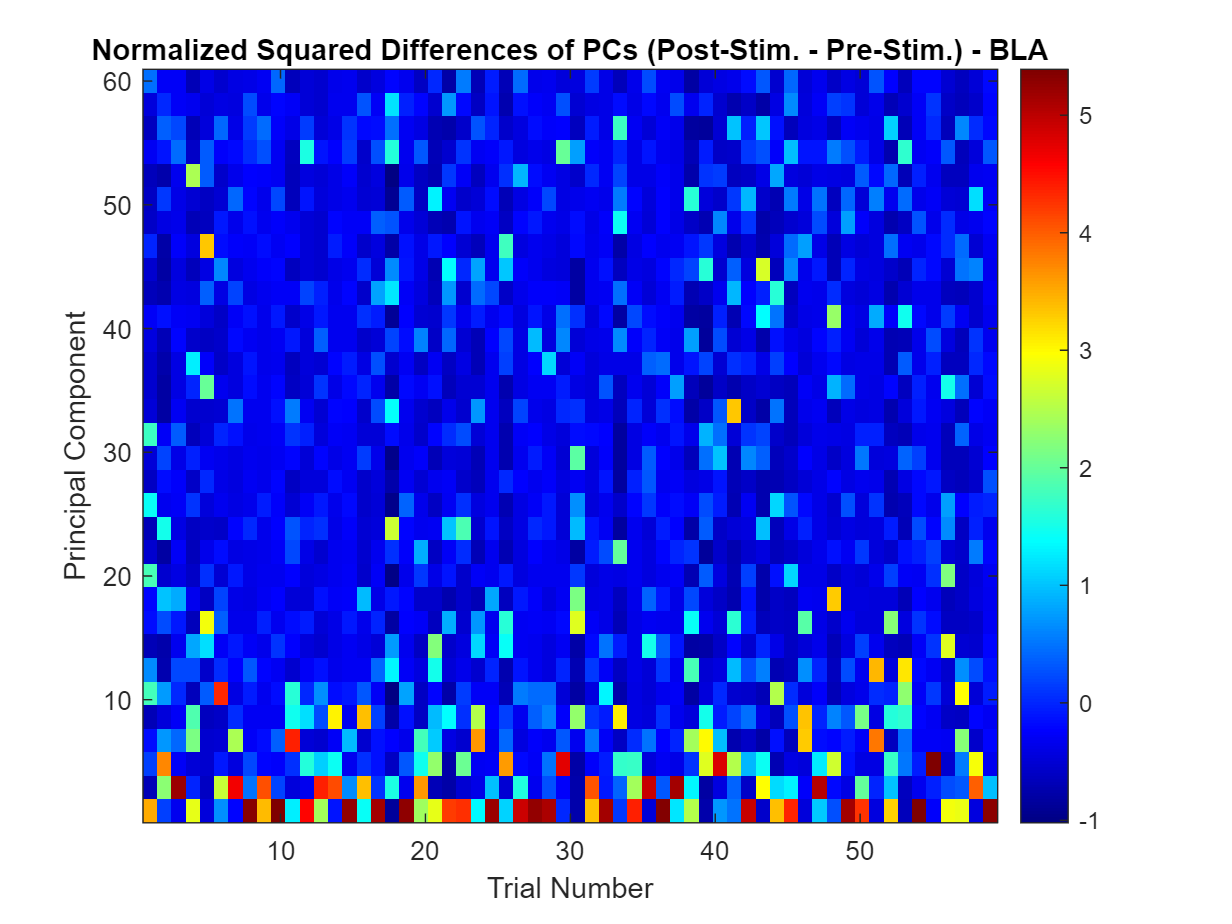

% % Plot heatmaps for 500ms and 2000ms trials separately
% 
% % Identify indices of 500ms and 2000ms trials
% idx_500 = ismember(epoch_trials, trials_500ms);
% idx_2000 = ismember(epoch_trials, trials_2000ms);
% 
% % Extract corresponding values
% pc_diff_squared_z_500 = pc_diff_squared_z(idx_500, :);
% pc_diff_squared_z_2000 = pc_diff_squared_z(idx_2000, :);
% 
% % Plot in subplots
% figure('Position', [100, 100, 1200, 400]); % [x, y, width, height]
% 
% % Subplot for 500ms trials
% subplot(1, 2, 1);
% imagesc(1:size(pc_diff_squared_z_500, 1), 1:(length(pc_diff_squared_z_500)), pc_diff_squared_z_500'); % PCs 1-15
% colorbar;
% xlabel('Trial Number');
% ylabel('Principal Component');
% title('500ms Trials: Normalized Squared Differences');
% set(gca, 'YDir', 'normal');
% colormap jet;
% 
% % Subplot for 2000ms trials
% subplot(1, 2, 2);
% imagesc(1:size(pc_diff_squared_z_2000, 1), 1:(length(pc_diff_squared_z_2000)), pc_diff_squared_z_2000'); % PCs 1-15
% colorbar;
% xlabel('Trial Number');
% ylabel('Principal Component');
% title('2000ms Trials: Normalized Squared Differences');
% set(gca, 'YDir', 'normal');
% colormap jet;
% 
% % Ensure proper layout
% sgtitle('Comparison of 500ms vs 2000ms Trials');

% Plot as heatmap
figure;
imagesc(1:length(epoch_trials)-1, 1:(length(pc_diff_squared_z)), pc_diff_squared_z'); % Transpose so PCs are on the y-axis
colorbar;
xlabel('Trial Number');
ylabel('Principal Component');
title(['Normalized Squared Differences of PCs (Post-Stim. - Pre-Stim.) - ' 'BLA']);
set(gca, 'YDir', 'normal'); % Ensure correct orientation
colormap jet;